# Chapter 5 ATAP Exercises

## Barycentric Interpolation Formula

#### Mason Mault June 2025

Worked exercises

Exercise 5.2: Instability of Vandermonde interpolation

Exercise 5.11: Barycentric Interpolation in Legendre Points

**Exercise 5.2: Instability of Vandermonde interpolation**

The best known numerical algorithm for polynomial interpolation is unstable. This is the method implemented by MATLABS polyfit command, forming a Vandermonde matrix of sampled powers of x, then solving the corresponding linear system. 

Here, the instability is explored by comparison to Chebyshev interpolation, specifically, the evaluation of the interpolation evaluation at 0, for the function

$f\left(x\right)=\cos \left(\textrm{kx}\right)$ for k = 10, 20, ..., 100

The Vandermonde matrix V is constructed for each of these 10 problems, and its condition number is computed

% build  a "fine grid"
fine = 1e4;
xx = linspace(-1, 1, fine);

% initialization
fkEval = zeros(10, 1);
pkEval = zeros(10, 1);
condNum = zeros(10, 1);

% start at k = 10, take steps of 10, until k = 100
for k = 10:10:100   
    % account for steps of 10 in index
    fk = @(x) cos(k*x);
    fkEval(k/10) = fk(0);
    pkEval(k/10) = polyval(polyfit(xx, fk(xx), k), 0);

    % build vandermonde matrix up to degree k, compute condition number
    V = vander(xx);
    V = V(:, end - k : end);
    condNum(k/10) = cond(V);
end

In the following, the value of k increases from top to bottom.

The 10 values of fk(0), the chebfun evaluations at 0, are

disp(fkEval)

     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



consistently providing the correct value.

On the other hand, the 10 values of pk(0), the polyfit evaluations at 0, are

disp(pkEval)

    0.8824
    0.8517
    0.8345
    0.7981
   -0.3365
    0.1722
    0.0195
    0.0782
    0.1013
    0.1353



which are clearly unstable, and get farther from the true value of 1 as k increases.

Below are the condition numbers for the Vandermonde matrices

condNum

condNum = 1.0e+18 *

    0.0000
    0.0000
    0.0000
    0.0007
    0.1529
    0.2148
    0.3026
    2.5196
    6.0523
    3.6814


Which are horrible.

**Exercise 5.11: Barycentric Interpolation in Legendre Points**

Compare the accuracy of interpolants in Chebyshev and Legendre points to the function

$f\left(x\right)=\exp \left(x\right)\;\sin \left(300x\right)$ at x = 0.99.

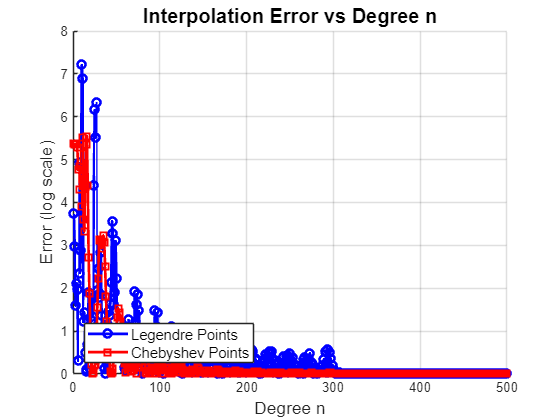

x = chebfun('x');
f = exp(x)*sin(300*x);

% number of iterations
niter = 500;

% initialization
legEval = zeros(niter, 1);
chebEval = zeros(niter, 1);
legErr = zeros(niter, 1);
chebErr = zeros(niter, 1);

% evaluate f(x) at x = 0.99 using both point sets
for n = 1:niter
    [s, w, lambda] = legpts(n + 1);
    legEval(n) = bary(0.99, f(s), s, lambda);
    legErr(n) = abs(legEval(n) - f(0.99));

    [s2, w2, lambda2] = chebpts(n + 1);
    chebEval(n) = bary(0.99, f(s2), s2, lambda2);
    chebErr(n) = abs(chebEval(n) - f(0.99));
end

% plot error vs n for both points
figure
hold on
semilogy(legErr, '-ob', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Legendre Points')
semilogy(chebErr, '-sr', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Chebyshev Points')

xlabel('Degree n', 'FontSize', 13)
ylabel('Error (log scale)', 'FontSize', 13)
title('Interpolation Error vs Degree n', 'FontSize', 15)

legend('Location', 'southwest', 'FontSize', 11)
grid on
xlim([0, 500])

Evaluating at x = 0.99 gives insight into how well the interpolations hug the true function near endpoints, which are known to be problematic.

The Chebyshev points give less error for almost all values of n.

Both point sets oscillate wrt error as a function of n.